run("master_setting_sheet.mlx");

Pitch Diameter(mm):47.00Addendum (mm):			1.00Deddendum (mm):			1.25Whole Depth (mm):		2.25Pitch Diameter(mm):26.00Addendum (mm):			1.00Deddendum (mm):			1.25Whole Depth (mm):		2.25Module (mm):			1.00Pitch Diameter(mm):		111.00Addendum (mm):			1.00Deddendum (mm):			1.25Whole Depth (mm):		2.25Module (mm):	     1.00Pitch Diameter(mm):  111.00Addendum (mm):	     1.00Deddendum (mm):	     1.25Whole Depth (mm):    2.25Gear Ratio: 8.43Housing Reaction at ring gear (Nm): 185.8


[err1, sun_stage_crown_radius,sun_stage_crown_drop] = getCrowning(planet.sunStage,planetPin.angleTolerance);
[err2, ring_stage_crown_radius,ring_stage_crown_drop] = getCrowning(planet.ringStage,planetPin.angleTolerance);

fprintf("For sun stage:")

For sun stage:

fprintf("The numerical error is: %.2e deg",err1);

The numerical error is: 1.61e-06 deg

fprintf("The required crowning radius is: %.2e m",sun_stage_crown_radius);

The required crowning radius is: 9.31e-02 m

fprintf("The required crown drop is %.2f um",sun_stage_crown_drop*10^6);

The required crown drop is 302.61 um


fprintf("For ring stage:")

For ring stage:

fprintf("The numerical error is: %.2e deg",err2);

The numerical error is: 1.61e-06 deg

fprintf("The required crowning radius is: %.2e m",ring_stage_crown_radius);

The required crowning radius is: 9.31e-02 m

fprintf("The required crown drop is %.2f um",ring_stage_crown_drop*10^6);

The required crown drop is 302.61 um

function [err,req_rf,y] = getCrowning(gear,angleTolerance) % numerical solution to the given deviation equation
    rf = linspace(0.001, 10,100000); % crown radius (m)
    
    chordal_thickness = (pi*gear.module)/(2*25.4);   % chordal thicknes/ thickness of the tooth at the pitch circle (m)
    costerm = acosd((2*rf-gear.pitchDiameter)...
        ./(2*rf-chordal_thickness)); %cosine term of the given equation
    sinterm = asind(gear.facewidth*0.5./2*rf); % sine term of the given equation
    min_func = angleTolerance - min(costerm,sinterm); % calculates the error between the given angle tolerance and the calculated angle tolerance for different values of rf
    [err,pos] = min(abs(min_func)); % returns the absolute deviations from the angle tolerance
    req_rf = rf(pos);
    y = req_rf-sqrt(req_rf^2-(gear.facewidth/2)^2);
end

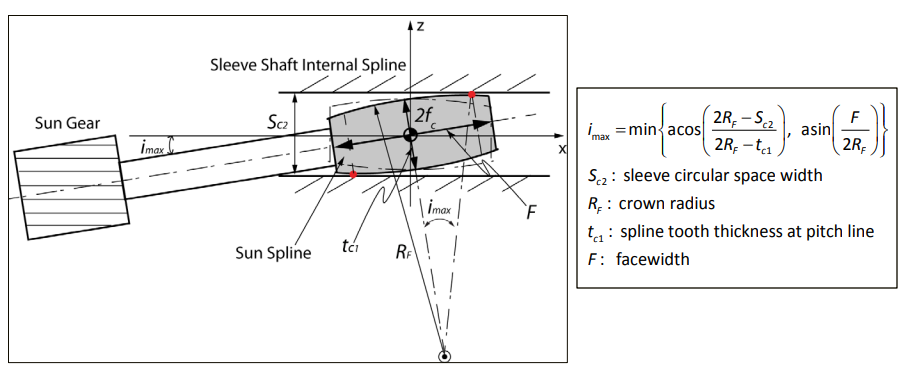

Calculation ([Source](http://nrel.gov/docs/fy15osti/62812.pdf)) is done for a spline but the same idea applies to gears.